# Averaging trials

## Exercise 3.3

% load dataset
clear;

if isfile('BI5_segments_HTS.mat')
    data = load('BI5_segments_HTS.mat');
else
    error('File BI5_segments_HTS.mat not found.');
end

segments = data.segments;
labels = data.classlabels;
t = data.t;
channels = data.ch_selection;

non_target_idx = find(labels == 1);
target_idx = find(labels == 2);

non_tar =  data.segments(:, :, non_target_idx);
tar = data.segments(:, :, target_idx);

% we use the Cz channel
Cz_non_tar = non_tar(2, :, :);
Cz_tar = tar(2, :, :);

% raw = signal we want to average 
% trials = number of trials averaged (3/5/10)
function avg_sign = average_function(raw, trials)

    % select the indices of the trials that we consider. 
    % from 1 to 'length of data', with 3/5/10 step size. last index is
    % removed.
    idxs = 1:trials:length(raw)-trials;
    avg_sign = zeros(size(raw,1), size(raw,2), length(idxs));
    
    % we use k as a counter so that we store the averaged trials in order
    % at 1, 2, 3,... instead of their original index.
    k = 1;
    for i = idxs
        j = i+trials-1;
        % i = start index
        % j = end index
        avg = mean(raw(1, :, (i:j)), 3);
        % fprintf('the mean from index %d to index %d is %.2f\n', i, j, avg(1));
        avg_sign(:, :, k) = avg;
        k = k + 1;
    end
end


% averaging every 3 trials
avg_tar_3 = average_function(Cz_tar, 3);
avg_non_tar_3 = average_function(Cz_non_tar, 3);

% averaging every 5 trials
avg_tar_5 = average_function(Cz_tar, 5);
avg_non_tar_5 = average_function(Cz_non_tar, 5);

% averaging every 10 trials
avg_tar_10 = average_function(Cz_tar, 10);
avg_non_tar_10 = average_function(Cz_non_tar, 10);

## Exercise 3.4

% splitting the data into train and test like in 3.1, but now we need to
% use a ratio of 50% instead of using hard-coded values, since the averaged
% trials are shorter than the original signal


## Function that splits data and performs cross validation (taken from ex 3.1)

function [mean_cv, std_cv] = split_cross_val(non_tar, tar)
    % use the avraging by 3
    current_non = non_tar; 
    current_tar = tar;
    
    n_non = size(current_non, 3);
    n_tar = size(current_tar, 3);
    
    % 50% split
    split_ratio = 0.5;
    cut_non = round(n_non * split_ratio);
    cut_tar = round(n_tar * split_ratio);
    
    % shuffle indices
    idx_non = randperm(n_non);
    idx_tar = randperm(n_tar);
    
    % Extract features directly (tp1=21 ~300ms, tp2=32 ~500ms)
    tp1 = 21; tp2 = 32;
    extract_avg = @(seg, idx, tp) squeeze(seg(1, tp, idx))'; 
    
    % X
    X_train = [extract_avg(current_non, idx_non(1:cut_non), tp1), ...
               extract_avg(current_tar, idx_tar(1:cut_tar), tp1); ...
               extract_avg(current_non, idx_non(1:cut_non), tp2), ...
               extract_avg(current_tar, idx_tar(1:cut_tar), tp2)];
    
    X_test  = [extract_avg(current_non, idx_non(cut_non+1:end), tp1), ...
               extract_avg(current_tar, idx_tar(cut_tar+1:end), tp1); ...
               extract_avg(current_non, idx_non(cut_non+1:end), tp2), ...
               extract_avg(current_tar, idx_tar(cut_tar+1:end), tp2)];
    
    % Y
    Y_train = [-ones(1, cut_non), ones(1, cut_tar)];
    Y_test  = [-ones(1, n_non - cut_non), ones(1, n_tar - cut_tar)];
    
    % fprintf('Training set: %d trials\n', size(X_train, 2));
    % fprintf('Test set:     %d trials\n', size(X_test, 2));
    
    X_all = X_train;
    Y_all = Y_train;
    num_repetitions = 10;
    num_folds = 10;
    all_accuracies = zeros(num_repetitions, num_folds);
    
    for rep = 1:num_repetitions
        indices = crossvalind('Kfold', Y_all, num_folds);
        for fold = 1:num_folds
            test_idx = (indices == fold);
            train_idx = ~test_idx;
    
            [~, ~, w_cv, b_cv, ~] = custom_LDA(X_all(:,train_idx), Y_all(train_idx), ...
                                                 X_all(:,test_idx),  Y_all(test_idx));
    
            % Balanced accuracy corrects for the class ratio 
            preds= sign(w_cv' * X_all(:,test_idx) + b_cv);
            acc_non = mean(preds(Y_all(test_idx) == -1) == -1);
            acc_tar = mean(preds(Y_all(test_idx) ==  1) ==  1);
            all_accuracies(rep, fold) = 0.5 * acc_non + 0.5 * acc_tar;
        end
    end
    
    [~, ~, w, b, ~] = custom_LDA(X_train, Y_train, X_test, Y_test);
    preds_test      = sign(w' * X_test + b);
    mean_cv = mean(all_accuracies(:));
    std_cv  = std(all_accuracies(:));
    
    fprintf('Mean CV Accuracy (balanced) : %.2f%%\n', mean_cv * 100);
    fprintf('Std  CV Accuracy            : %.2f%%\n', std_cv  * 100);

end

## computing cross validation over the three averaged signals

[mean_3, std_3] = split_cross_val(avg_non_tar_3, avg_tar_3);

Test Set Accuracy: 86.11%
Train Set Accuracy: 86.10%
Test Set Accuracy: 83.78%
Train Set Accuracy: 86.36%
Test Set Accuracy: 83.78%
Train Set Accuracy: 85.45%
Test Set Accuracy: 83.78%
Train Set Accuracy: 86.36%
Test Set Accuracy: 89.19%
Train Set Accuracy: 83.94%
Test Set Accuracy: 88.89%
Train Set Accuracy: 85.50%
Test Set Accuracy: 86.11%
Train Set Accuracy: 85.80%
Test Set Accuracy: 91.89%
Train Set Accuracy: 85.15%
Test Set Accuracy: 81.08%
Train Set Accuracy: 86.97%
Test Set Accuracy: 83.78%
Train Set Accuracy: 84.85%
Test Set Accuracy: 88.89%
Train Set Accuracy: 84.89%
Test Set Accuracy: 83.78%
Train Set Accuracy: 86.06%
Test Set Accuracy: 80.56%
Train Set Accuracy: 86.71%
Test Set Accuracy: 86.49%
Train Set Accuracy: 85.45%
Test Set Accuracy: 89.19%
Train Set Accuracy: 84.24%
Test Set Accuracy: 83.33%
Train Set Accuracy: 86.40%
Test Set Accuracy: 86.49%
Train Set Accuracy: 85.45%
Test Set Accuracy: 83.78%
Train Set Accuracy: 86.67%
Test Set Accuracy: 89.19%
Train Set Accuracy: 

[mean_5, std_5] = split_cross_val(avg_non_tar_5, avg_tar_5);

Test Set Accuracy: 90.91%
Train Set Accuracy: 88.89%
Test Set Accuracy: 86.36%
Train Set Accuracy: 88.38%
Test Set Accuracy: 86.36%
Train Set Accuracy: 89.39%
Test Set Accuracy: 95.45%
Train Set Accuracy: 88.38%
Test Set Accuracy: 86.36%
Train Set Accuracy: 88.38%
Test Set Accuracy: 86.36%
Train Set Accuracy: 89.39%
Test Set Accuracy: 95.45%
Train Set Accuracy: 88.38%
Test Set Accuracy: 86.36%
Train Set Accuracy: 89.90%
Test Set Accuracy: 81.82%
Train Set Accuracy: 88.89%
Test Set Accuracy: 90.91%
Train Set Accuracy: 88.89%
Test Set Accuracy: 86.36%
Train Set Accuracy: 88.38%
Test Set Accuracy: 90.91%
Train Set Accuracy: 89.39%
Test Set Accuracy: 86.36%
Train Set Accuracy: 88.38%
Test Set Accuracy: 95.45%
Train Set Accuracy: 88.38%
Test Set Accuracy: 86.36%
Train Set Accuracy: 88.89%
Test Set Accuracy: 86.36%
Train Set Accuracy: 88.38%
Test Set Accuracy: 90.91%
Train Set Accuracy: 88.89%
Test Set Accuracy: 95.45%
Train Set Accuracy: 87.88%
Test Set Accuracy: 81.82%
Train Set Accuracy: 

[mean_10, std_10] = split_cross_val(avg_non_tar_10, avg_tar_10);

Test Set Accuracy: 100.00%
Train Set Accuracy: 93.94%
Test Set Accuracy: 100.00%
Train Set Accuracy: 93.94%
Test Set Accuracy: 100.00%
Train Set Accuracy: 93.94%
Test Set Accuracy: 100.00%
Train Set Accuracy: 93.94%
Test Set Accuracy: 90.91%
Train Set Accuracy: 94.95%
Test Set Accuracy: 81.82%
Train Set Accuracy: 95.96%
Test Set Accuracy: 100.00%
Train Set Accuracy: 93.94%
Test Set Accuracy: 90.91%
Train Set Accuracy: 94.95%
Test Set Accuracy: 90.91%
Train Set Accuracy: 94.95%
Test Set Accuracy: 90.91%
Train Set Accuracy: 94.95%
Test Set Accuracy: 81.82%
Train Set Accuracy: 95.96%
Test Set Accuracy: 100.00%
Train Set Accuracy: 93.94%
Test Set Accuracy: 100.00%
Train Set Accuracy: 93.94%
Test Set Accuracy: 90.91%
Train Set Accuracy: 94.95%
Test Set Accuracy: 100.00%
Train Set Accuracy: 93.94%
Test Set Accuracy: 90.91%
Train Set Accuracy: 94.95%
Test Set Accuracy: 90.91%
Train Set Accuracy: 94.95%
Test Set Accuracy: 100.00%
Train Set Accuracy: 93.94%
Test Set Accuracy: 100.00%
Train Set 

## comparison with previous results

mean_ass_2 = 0.5336;
mean_ass_3_2 = 0.5392;
std_ass_3_2 = 0.0307;

## plotting the comparison between averaged trials

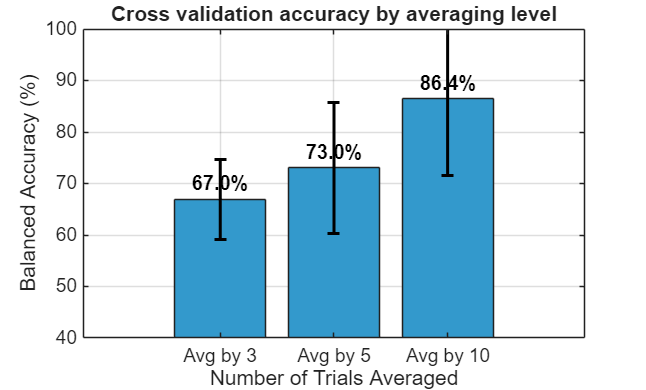

means_to_plot = [mean_3, mean_5, mean_10] * 100;
stds_to_plot  = [std_3,  std_5,  std_10] * 100;
categories    = {'Avg by 3', 'Avg by 5', 'Avg by 10'};

% 2. Create the bar plot
figure;
b = bar(means_to_plot, 'FaceColor', [0.2 0.6 0.8]); % Nice blue color
hold on;

% 3. Add error bars (representing the Standard Deviation)
% 'k' makes them black, 'linestyle', 'none' prevents connecting lines
errorbar(1:3, means_to_plot, stds_to_plot, 'k', 'linestyle', 'none', 'LineWidth', 1.5);

% 4. Formatting the chart
set(gca, 'XTickLabel', categories);
ylabel('Balanced Accuracy (%)');
xlabel('Number of Trials Averaged');
title('Cross validation accuracy by averaging level');
grid on;

% Set Y-axis to focus on the relevant range (e.g., 40% to 100%)
ylim([40 100]); 

% Add text labels directly on top of the bars (the means)
for i = 1:length(means_to_plot)
    text(i, means_to_plot(i) + 1, ... % Position 1% above the bar height
         sprintf('%.1f%%', means_to_plot(i)), ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'bottom', ... 
         'FontWeight', 'bold', ...
         'Color', 'black');
end

hold off;

## plotting comparison between averaged trials and previous results

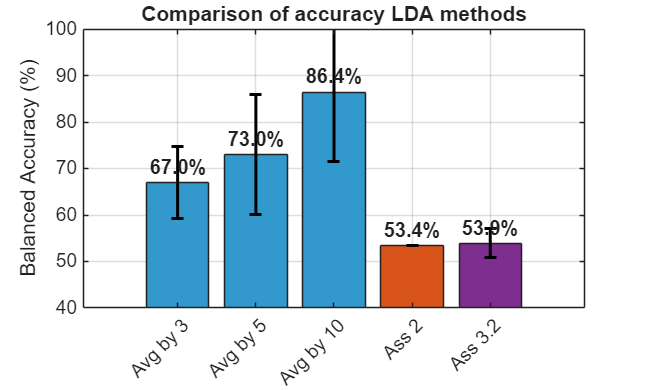

% 1. Prepare the data (Converting all to percentages)
% Assuming mean_3, std_3, etc. are already defined in your workspace
means_to_plot = [mean_3, mean_5, mean_10, mean_ass_2, mean_ass_3_2] * 100;

% For mean_ass_2, we use 0 for the standard deviation since it wasn't provided
stds_to_plot  = [std_3, std_5, std_10, 0, std_ass_3_2] * 100;

categories = {'Avg by 3', 'Avg by 5', 'Avg by 10', 'Ass 2', 'Ass 3.2'};

% 2. Create the bar plot
figure;
b = bar(means_to_plot);
b.FaceColor = 'flat'; % Allows individual bar coloring

% 3. Set specific colors
% Colors are in [Red Green Blue] format from 0 to 1
blue_color   = [0.2 0.6 0.8]; % Original blue
orange_color = [0.85 0.33 0.1]; % Distinct orange for Method 2
purple_color = [0.49 0.18 0.56]; % Distinct purple for Method 3.2

% Apply colors to the bars
b.CData(1,:) = blue_color;   % Avg 3
b.CData(2,:) = blue_color;   % Avg 5
b.CData(3,:) = blue_color;   % Avg 10
b.CData(4,:) = orange_color; % Method 2
b.CData(5,:) = purple_color; % Method 3.2

hold on;

% 4. Add error bars
% Note: The 4th error bar will be 0 (no line shown)
errorbar(1:5, means_to_plot, stds_to_plot, 'k', 'linestyle', 'none', 'LineWidth', 1.5);

% 5. Add text labels on top of the bins (bars)
for i = 1:length(means_to_plot)
    text(i, means_to_plot(i) + 1, ... % 1% offset above the bar
         sprintf('%.1f%%', means_to_plot(i)), ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'bottom', ...
         'FontWeight', 'bold');
end

% 6. Formatting
set(gca, 'XTickLabel', categories);
set(gca, 'XTickLabelRotation', 45);
set(gca, 'XTickLabel', categories);
ylabel('Balanced Accuracy (%)');
title('Comparison of accuracy LDA methods');
ylim([40 100]); % Focused range for accuracy
grid on;
hold off;